spectra = importdata('spectra.csv')

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


starNames = importdata("star_names.csv")

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


lambdaStart = importdata("lambda_start.csv")

lambdaStart = 630.0200

lambdaDelta = importdata("lambda_delta.csv")

lambdaDelta = 0.1400



NObs = size(spectra, 1)

NObs = 357

NStars = size(starNames, 1)

NStars = 7

lambdaEnd = lambdaStart + (NObs - 1)*lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart : lambdaDelta : lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800



j = 0

j = 0

ymax = 0

ymax = 0

lambdaTrue = 656.28

lambdaTrue = 656.2800

c = 299792.458

c = 2.9979e+05

speed = zeros(NStars, 1)

speed =      0
     0
     0
     0
     0
     0
     0


sHalist = zeros(NStars, 1)

sHalist =      0
     0
     0
     0
     0
     0
     0


idxlist = zeros(NStars, 1)

idxlist =      0
     0
     0
     0
     0
     0
     0


movaway = zeros(NStars, 1)

movaway =      0
     0
     0
     0
     0
     0
     0


movaway = num2cell(movaway)

movaway = 7×1 cell array
    {[0]}
    {[0]}
    {[0]}
    {[0]}
    {[0]}
    {[0]}
    {[0]}



fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


for i = 1:1:NStars
    s = spectra(:, i)
    [sHa, idx] = min(s)
    
    if ymax < max(s)
        ymax = max(s)
    end
    
    lambdaHa = lambda(idx)
    sHalist(i) = sHa
    idxlist(i) = idx
    z = (lambdaHa / lambdaTrue) - 1
    speedi = z*c
    speed(i) = speedi
    
    if speedi < 0
        plot(lambda, s, "--", 'LineWidth', 1)
    else
        plot(lambda, s, "-", 'LineWidth', 3)
        j = j + 1
        movaway(j) = starNames(i)
    end
    
    grid on
    xlabel('Длина волны, нм')
    ylabel(['Интенсивность излучения, эрг/см^2/с/', char(197)])
    title('Спектры звезд')
    hold on
end

s = 	1.0e+-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


sHa = 1.6340e-13

idx = 188

ymax = 3.1360e-13

lambdaHa = 656.2000

sHalist = 	1.0e+-12 *

    0.1634
         0
         0
         0
         0
         0
         0


idxlist =    188
     0
     0
     0
     0
     0
     0


z = -1.2190e-04

speedi = -36.5445

speed =   -36.5445
         0
         0
         0
         0
         0
         0


s = 	1.0e+-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


sHa = 7.2400e-14

idx = 187

lambdaHa = 656.0600

sHalist = 	1.0e+-12 *

    0.1634
    0.0724
         0
         0
         0
         0
         0


idxlist =    188
   187
     0
     0
     0
     0
     0


z = -3.3522e-04

speedi = -100.4973

speed =   -36.5445
 -100.4973
         0
         0
         0
         0
         0


s = 	1.0e+-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


sHa = 3.1440e-14

idx = 188

lambdaHa = 656.2000

sHalist = 	1.0e+-12 *

    0.1634
    0.0724
    0.0314
         0
         0
         0
         0


idxlist =    188
   187
   188
     0
     0
     0
     0


z = -1.2190e-04

speedi = -36.5445

speed =   -36.5445
 -100.4973
  -36.5445
         0
         0
         0
         0


s = 	1.0e+-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


sHa = 5.3640e-14

idx = 189

lambdaHa = 656.3400

sHalist = 	1.0e+-12 *

    0.1634
    0.0724
    0.0314
    0.0536
         0
         0
         0


idxlist =    188
   187
   188
   189
     0
     0
     0


z = 9.1424e-05

speedi = 27.4083

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
         0
         0
         0


j = 1

movaway = 7×1 cell array
    {'HD5211'}
    {[     0]}
    {[     0]}
    {[     0]}
    {[     0]}
    {[     0]}
    {[     0]}


s = 	1.0e+-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


sHa = 6.8980e-14

idx = 189

lambdaHa = 656.3400

sHalist = 	1.0e+-12 *

    0.1634
    0.0724
    0.0314
    0.0536
    0.0690
         0
         0


idxlist =    188
   187
   188
   189
   189
     0
     0


z = 9.1424e-05

speedi = 27.4083

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
         0
         0


j = 2

movaway = 7×1 cell array
    {'HD5211' }
    {'HD56030'}
    {[      0]}
    {[      0]}
    {[      0]}
    {[      0]}
    {[      0]}


s = 	1.0e+-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


sHa = 9.8010e-14

idx = 191

lambdaHa = 656.6200

sHalist = 	1.0e+-12 *

    0.1634
    0.0724
    0.0314
    0.0536
    0.0690
    0.0980
         0


idxlist =    188
   187
   188
   189
   189
   191
     0


z = 5.1807e-04

speedi = 155.3139

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
         0


j = 3

movaway = 7×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}
    {[      0]}
    {[      0]}
    {[      0]}
    {[      0]}


s = 	1.0e+-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


sHa = 2.2140e-14

idx = 185

lambdaHa = 655.7800

sHalist = 	1.0e+-12 *

    0.1634
    0.0724
    0.0314
    0.0536
    0.0690
    0.0980
    0.0221


idxlist =    188
   187
   188
   189
   189
   191
   185


z = -7.6187e-04

speedi = -228.4029

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


legend(starNames)
movaway = movaway(1 : j)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


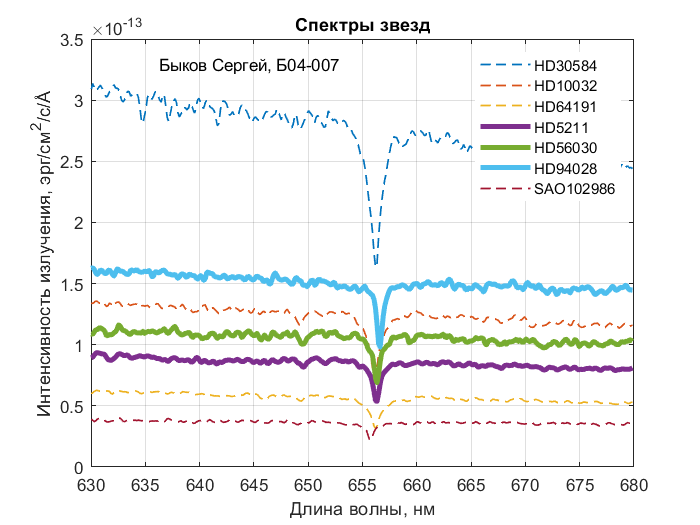

text((((lambdaStart + lambdaEnd)/2 + lambdaStart)/2 + lambdaStart)/2, ymax*1.05, 'Быков Сергей, Б04-007')
set(fg1, 'visible', 'on')
hold off

saveas(fg1, 'spectraplot', 'png')